## Dubins Path Computation

Helper script to compute shortest dubin's path. Define the test input.

startPose = [0, 0, pi/4];
goalPose = [1, 1, 0];

### This is showing the matlab's Dubin functionality (from robotics toolbox) - used as a reference to validate our implementation.

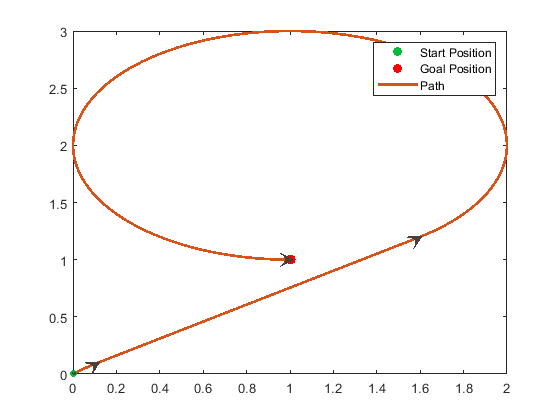

conn = robotics.DubinsConnection;
% conn.MinTurningRadius = 4;
pathCalculator = connect(conn,startPose, goalPose);
pathSeg = pathCalculator{1};
show(pathSeg);

fprintf('path : %s\n', pathSeg.MotionLengths);

path : 1.473205e-01
path : 1.847759e+00
path : 5.645108e+00


fprintf('optimalMode : %s\n', strjoin(pathSeg.MotionTypes));

optimalMode : R S L


fprintf('optimalCost : %s\n', pathSeg.Length);

optimalCost : 7.640187e+00


### This is from our implementation. The values shown here should match the values shown above.

computeDubinsPath(startPose, goalPose, 1);

path : 1.473205e-01
path : 1.847759e+00
path : 5.645108e+00
optimalMode : RSL
optimalCost : 7.640187e+00


function computeDubinsPath(start, goal, minTurn)
    c = 1 / minTurn;
    
    diff = goal - start;
    lex = cos(start(3)) * diff(1) + sin(start(3)) * diff(2);
    ley = -1.0 * sin(start(3)) * diff(1) + cos(start(3)) * diff((2));
    
    [path, optimalMode, optimalCost] = computeDubinsInternal([lex, ley, diff(3)], c);
    
    fprintf('path : %s\n', path);
    fprintf('optimalMode : %s\n', optimalMode);
    fprintf('optimalCost : %s\n', optimalCost);
end

function [path, optimalMode, optimalCost] = computeDubinsInternal(diff, c)
    D = norm(diff(1:2));
    theta = wrapTo2Pi(atan2(diff(2), diff(1)));
    alpha = wrapTo2Pi(0.0 - theta);
    beta = wrapTo2Pi(diff(3) - theta);
    
    optimalCost = inf;
    optimalMode = nan;
    path = nan;
    allModes = {@LSL, @RSR, @LSR, @RSL, @RLR, @LRL};
    
    for i = 1:length(allModes)
        [t1, t2, t3, mode] = allModes{i}(alpha, beta, D * c);
        currentCost = abs(t1) + abs(t2) + abs(t3);
        if ((~isnan(t1)) && (currentCost < optimalCost))
            optimalCost = currentCost;
            [best_t1, best_t2, best_t3, optimalMode] = deal(t1, t2, t3, mode);
        end
    end
    
    if (~isnan(optimalMode))
        path = [best_t1, best_t2, best_t3];
    end
end

function [t1, t2, t3, mode] = LSL(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['L', 'S', 'L'];
    
    p_squared = 2 + (d * d) - (2 * c_ab) + (2 * d * (sa - sb));
    
    if (p_squared < 0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        tmp0 = d + sa - sb;
        tmp1 = atan2((cb-ca), tmp0);
        t1 = wrapTo2Pi(-alpha + tmp1);
        t2 = sqrt(p_squared);
        t3 = wrapTo2Pi(beta - tmp1);
    end
end

function [t1, t2, t3, mode] = RSR(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['R', 'S', 'R'];
    
    p_squared = 2 + (d * d) - (2 * c_ab) + (2 * d * (sb - sa));
    
    if (p_squared < 0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        tmp0 = d - sa + sb;
        tmp1 = atan2((ca-cb), tmp0);
        t1 = wrapTo2Pi(alpha - tmp1);
        t2 = sqrt(p_squared);
        t3 = wrapTo2Pi(-beta + tmp1);
    end
end

function [t1, t2, t3, mode] = LSR(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['L', 'S', 'R'];
    
    p_squared = -2 + (d * d) + (2 * c_ab) + (2 * d * (sa + sb));
    
    if (p_squared < 0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        tmp0 = d + sa + sb;
        t2 = sqrt(p_squared);
        tmp1 = atan2((-cb-ca), tmp0) - atan2(-2.0, t2);
        t1 = wrapTo2Pi(-alpha + tmp1);
        t3 = wrapTo2Pi(-wrapTo2Pi(beta) + tmp1);
    end
end

function [t1, t2, t3, mode] = RSL(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['R', 'S', 'L'];
    
    p_squared = -2 + (d * d) + (2 * c_ab) - (2 * d * (sa + sb));
    
    if (p_squared < 0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        t2 = sqrt(p_squared);
        tmp0 = d - sa - sb;
        tmp1 = atan2((cb+ca), tmp0) - atan2(2.0, t2);
        t1 = wrapTo2Pi(alpha - tmp1);
        t3 = wrapTo2Pi(beta - tmp1);
    end
end

function [t1, t2, t3, mode] = RLR(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['R', 'L', 'R'];
    
    tmp_rlr = (6.0 - (d * d) + (2.0 * c_ab) + (2.0 * d * (sa - sb))) / 8.0;
    
    if (abs(tmp_rlr) > 1.0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        t2 = wrapTo2Pi((2 * pi) - acos(tmp_rlr));
        tmp0 = d - sa + sb;
        tmp1 = atan2((ca-cb), tmp0);
        t1 = wrapTo2Pi(alpha - tmp1 + wrapTo2Pi(t2 / 2.0));
        t3 = wrapTo2Pi(alpha - beta - t1 + wrapTo2Pi(t2));
    end
end

function [t1, t2, t3, mode] = LRL(alpha, beta, d)
    sa = sin(alpha);
    sb = sin(beta);
    ca = cos(alpha);
    cb = cos(beta);
    c_ab = cos(alpha - beta);
    mode = ['L', 'R', 'L'];
    
    tmp_lrl = (6.0 - (d * d) + (2.0 * c_ab) + (2.0 * d * (- sa + sb))) / 8.0;
    
    if (abs(tmp_lrl) > 1.0)
        [t1, t2, t3] = deal(nan, nan, nan);
    else
        t2 = wrapTo2Pi((2 * pi) - acos(tmp_lrl));
        tmp0 = d + sa - sb;
        tmp1 = atan2((ca-cb), tmp0);
        t1 = wrapTo2Pi(-alpha - tmp1 + (t2/2.0));
        t3 = wrapTo2Pi(wrapTo2Pi(beta) - alpha - t1 + wrapTo2Pi(t2));
    end
end

## References

[https://courses.cs.washington.edu/courses/cse490r/18wi/homework/dubins_path_planning.pdf](https://courses.cs.washington.edu/courses/cse490r/18wi/homework/dubins_path_planning.pdf)

[https://gitlab.cs.washington.edu/cse490r_18wi/lab4/blob/master/src/Dubins.py](https://gitlab.cs.washington.edu/cse490r_18wi/lab4/blob/master/src/Dubins.py)